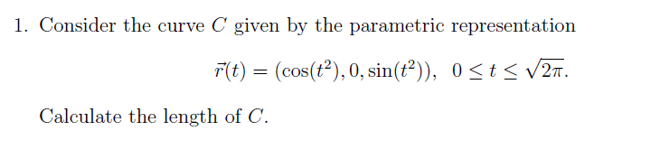

clear
syms t

r(t) = [cos(t^2), sym(0), sin(t^2)]

$$r(t) = \left(\begin{array}{ccc} \cos\left(t^{2}\right) & 0 & \sin\left(t^{2}\right) \end{array}\right)$$


r_diff(t) = diff(r(t), t)

$$r\_diff(t) = \left(\begin{array}{ccc} -2\,t\,\sin\left(t^{2}\right) & 0 & 2\,t\,\cos\left(t^{2}\right) \end{array}\right)$$


a = sym(0);
b = sqrt(2*pi);



L = int((sqrt(dot(r_diff(t), r_diff(t)))), t, a, b)

$$L = \int_{0}^{\frac{5644425081792261}{2251799813685248}}2\,\sqrt{t\,\cos\left(t^{2}\right)\,\cos\left({\left(\bar{t}\right)}^{2}\right)\,\bar{t}+t\,\sin\left(t^{2}\right)\,\sin\left({\left(\bar{t}\right)}^{2}\right)\,\bar{t}}\mathrm{d}t$$


L = vpa(L, 3)

$$L = 6.28$$



2*pi % Er det samme som L så alt godt. 

ans = 6.2832

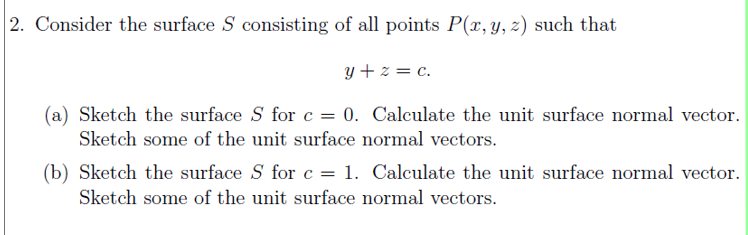

clear
clf;

syms y z x
f(x,y,z) = y+z

$$f(x, y, z) = y+z$$


gradient(f(x,y,z))

$$ans = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$


vf = [0,1,1]

vf =      0     1     1



vf/norm(vf)

ans =          0    0.7071    0.7071



1/norm(vf) % OK!

ans = 0.7071

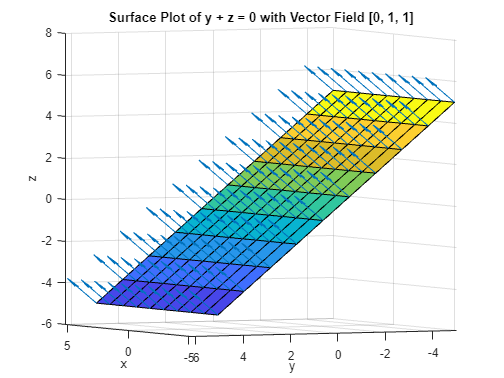


% Opg B

% Det samme stort set, vi rykke bare flade nen tak 

% Define the range for x and y
x = linspace(-5, 5, 10); % Adjust the range and density as needed
y = linspace(-5, 5, 10);

% Create a meshgrid for x and y
[X, Y] = meshgrid(x, y);

% Define the surface z = -y
Z = -Y;

% Plot the surface
surf(X, Y, Z)
hold on; % Keep the surface plot and overlay the vector field
xlabel('x')
ylabel('y')
zlabel('z')
title('Surface Plot of y + z = 0 with Vector Field [0, 1, 1]')

% Vector field [0, 1, 1] for each point
U = zeros(size(X)); % x-component of the vector field is 0
V = ones(size(Y));  % y-component of the vector field is 1
W = ones(size(Z));  % z-component of the vector field is 1

% Scale factor for the vectors to make them visible but not too large
scaleFactor = 1;

% Plot the vector field
quiver3(X, Y, Z, U, V, W, scaleFactor);

hold off; % Release the figure for other plots

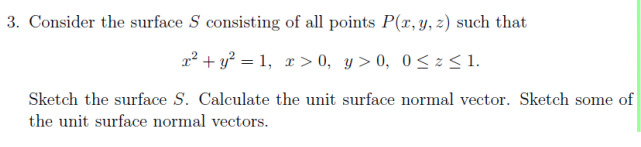

clear
syms x y z

solve(x^2 +y^2 == 1, x)

$$ans = \left(\begin{array}{c} \sqrt{1-y}\,\sqrt{y+1}\\ -\sqrt{1-y}\,\sqrt{y+1} \end{array}\right)$$


f(x,y,z) = x^2+y^2

$$f(x, y, z) = x^{2}+y^{2}$$


gradient(f(x,y,z))

$$ans = \left(\begin{array}{c} 2\,x\\ 2\,y \end{array}\right)$$


vf = [2*x, 2*y, 0]

$$vf = \left(\begin{array}{ccc} 2\,x & 2\,y & 0 \end{array}\right)$$


normlVector = vf/norm(vf)

$$normlVector = \left(\begin{array}{ccc} \frac{2\,x}{\sqrt{4\,{\left|x\right|}^{2}+4\,{\left|y\right|}^{2}}} & \frac{2\,y}{\sqrt{4\,{\left|x\right|}^{2}+4\,{\left|y\right|}^{2}}} & 0 \end{array}\right)$$


simplify(normlVector)

$$ans = \left(\begin{array}{ccc} \frac{x}{\sqrt{{\left|x\right|}^{2}+{\left|y\right|}^{2}}} & \frac{y}{\sqrt{{\left|x\right|}^{2}+{\left|y\right|}^{2}}} & 0 \end{array}\right)$$



x/sqrt(1)

$$ans = x$$

    
y/sqrt(1)

$$ans = y$$

Unit surface normal vector at (0.70711,0.70711,0.5) is: (0.70711,0.70711,0)


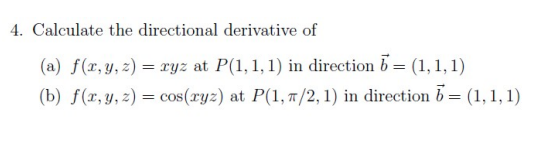

clear

syms x y z

% Opg a

f(x,y,z) = x*y*z

$$f(x, y, z) = x\,y\,z$$


vf(x,y,z) = gradient(f(x,y,z))

$$vf(x, y, z) = \left(\begin{array}{c} y\,z\\ x\,z\\ x\,y \end{array}\right)$$


vf_P = vf(1, 1, 1)

$$vf\_P = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$


b = [1, 1, 1]

b =      1     1     1



dbf = (b*vf_P / norm(b))

$$dbf = \sqrt{3}$$


% opg b

clear

syms x y z

f(x,y,z) = cos(x * y * z)

$$f(x, y, z) = \cos\left(x\,y\,z\right)$$


vf(x,y,z) = gradient(f(x,y,z))

$$vf(x, y, z) = \left(\begin{array}{c} -y\,z\,\sin\left(x\,y\,z\right)\\ -x\,z\,\sin\left(x\,y\,z\right)\\ -x\,y\,\sin\left(x\,y\,z\right) \end{array}\right)$$


vf_P = vf(1, pi/2, 1)

$$vf\_P = \left(\begin{array}{c} -\frac{\pi }{2}\\ -1\\ -\frac{\pi }{2} \end{array}\right)$$


b = [1, 1, 1]

b =      1     1     1



dbf = (b*vf_P / norm(b))

$$dbf = -\frac{\sqrt{3}\,\left(\pi +1\right)}{3}$$


simplify(dbf)

$$ans = -\frac{\sqrt{3}\,\left(\pi +1\right)}{3}$$

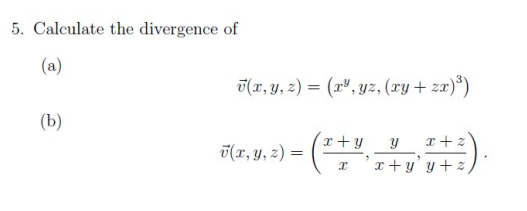

clear
syms x y z

%Opg A
v(x, y, z) = [x^y, y*z, (x*y + z*x)^3]

$$v(x, y, z) = \left(\begin{array}{ccc} x^{y} & y\,z & {\left(x\,y+x\,z\right)}^{3} \end{array}\right)$$



simplify(divergence(v))

$$ans(x, y, z) = z+3\,x\,{\left(x\,y+x\,z\right)}^{2}+x^{y-1}\,y$$


%Opg B
clear
syms x y z
v(x,y,z) = [(x+y)/x, y/(z+y), (x+z)/(y+z)]

$$v(x, y, z) = \left(\begin{array}{ccc} \frac{x+y}{x} & \frac{y}{y+z} & \frac{x+z}{y+z} \end{array}\right)$$


simplify(divergence(v))

$$ans(x, y, z) = -\frac{x^{3}-x^{2}\,y-x^{2}\,z+y^{3}+2\,y^{2}\,z+y\,z^{2}}{x^{2}\,{\left(y+z\right)}^{2}}$$